clc; clear; close all;

#### Setup

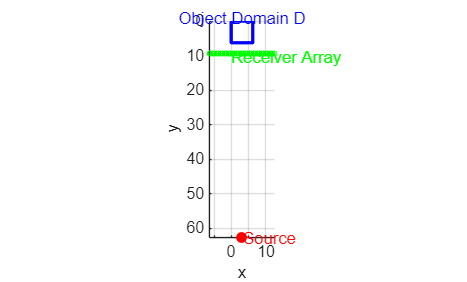

% Parameters
kb = 1;
lambda = 2*pi / 1; % Assuming kb = 1 (lambda = 2*pi / kb)
rho_s = [lambda/2; 10*lambda];

% Object domain D: rectangle from (0,0) to (lambda, lambda)
x_rect = [0, lambda, lambda, 0, 0];
y_rect = [0, 0, lambda, lambda, 0];

% Receiver line
M = 50; % Number of receivers
x_rec = linspace(-lambda, 2*lambda, M);
y_rec = 1.5 * lambda * ones(size(x_rec));

% Plot
figure;
hold on;
plot(x_rect, y_rect, 'b-', 'LineWidth', 2);                     % Object domain
plot(rho_s(1), rho_s(2), 'ro', 'MarkerFaceColor', 'r');         % Source
plot(x_rec, y_rec, 'g-o', 'LineWidth', 0.5, 'MarkerSize', 3);   % Receiver line

% Labels and formatting
text(rho_s(1)+0.2, rho_s(2), 'Source', 'Color', 'r');
text(lambda/2, -1, 'Object Domain D', 'Color', 'b', ...
    'HorizontalAlignment', 'center');
text(0, 1.5 * lambda + 1, 'Receiver Array', 'Color', 'g');
xlabel('x');
ylabel('y');
axis equal tight;
grid on;
set(gca, 'YDir', 'reverse'); % Flip y-direction like matrix coordinates

% title('Configuration of Object Domain and Source');

% Grid setup for object domain sampling
h = lambda / 20;    % Sample step
x = 0:h:lambda;
y = 0:h:lambda;

% Create meshgrid (for field evaluations in the object domain)
[X, Y] = meshgrid(x, y);

% Create mesh grid around the source to visuzalize the incident field
% around the source
[x_around_source, y_around_source] = meshgrid(linspace(rho_s(1)- 8 * lambda/4, rho_s(1)+ 8 * lambda/4, 50), ...
                           linspace(rho_s(2)- 8 * lambda/4, rho_s(2)+ 8 * lambda/4, 50));

% Total number of grid points
n = length(x);       % = 21
N = n * n;           % = 441

fprintf('Grid step size h = %.4f\n', h);

Grid step size h = 0.3142


fprintf('Grid points per axis = %d\n', n);

Grid points per axis = 21


fprintf('Total number of grid points N = %d\n', N);

Total number of grid points N = 441


## Visualize the incident field around the source

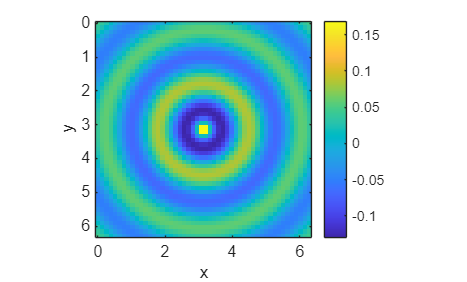

% Compute distance from each grid point (X, Y) to source (rho_s)
R_around_source = sqrt((x_around_source - rho_s(1)).^2 + (y_around_source - rho_s(2)).^2);

% Compute the incident field using Hankel function of the second kind
u_inc_around_source = -1i/4 * besselh(0, 2, kb * R_around_source);

% Plot: real part
figure;
imagesc(x, y, real(u_inc_around_source));
axis equal tight;
% title('Real Part of Incident Field Around the Source');
xlabel('x'), ylabel('y');
set(gca, 'YDir', 'reverse');
colorbar;

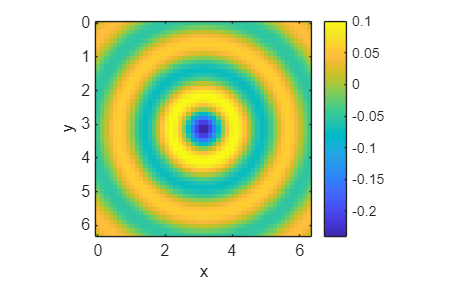


% Plot: imaginary part
figure;
imagesc(x, y, imag(u_inc_around_source));
axis equal tight;
% title('Imaginary Part of Incident Field Around the Source');
xlabel('x'), ylabel('y');
set(gca, 'YDir', 'reverse');
colorbar;

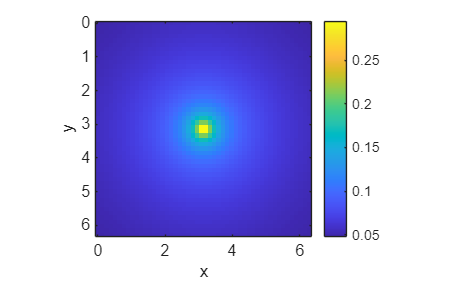


% Plot: absolute value
figure;
imagesc(x, y, abs(u_inc_around_source));
axis equal tight;
% title('Magnitude of Incident Field Around the Source');
xlabel('x'), ylabel('y');
set(gca, 'YDir', 'reverse');
colorbar;

## Visualize the incident field in the object domain

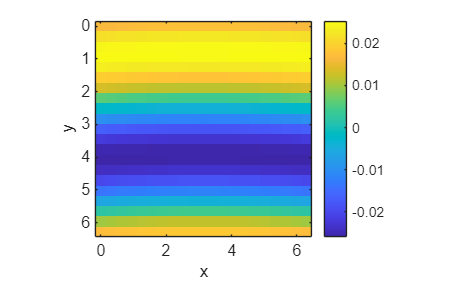

% Compute distance from each grid point (X, Y) to source (rho_s)
R = sqrt((X - rho_s(1)).^2 + (Y - rho_s(2)).^2);

% Compute the incident field using Hankel function of the second kind
u_inc = -1i/4 * besselh(0, 2, kb * R);

% Plot: real part
figure;
imagesc(x, y, real(u_inc));
axis equal tight;
% title('Real Part of Incident Field');
xlabel('x'), ylabel('y');
set(gca, 'YDir', 'reverse');
colorbar;

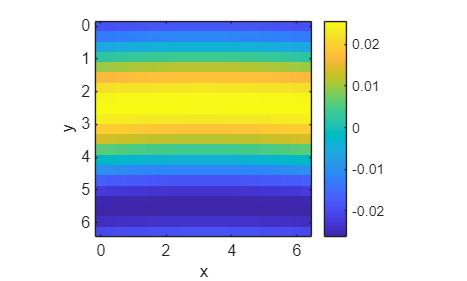


% Plot: imaginary part
figure;
imagesc(x, y, imag(u_inc));
axis equal tight;
% title('Imaginary Part of Incident Field');
xlabel('x'), ylabel('y');
set(gca, 'YDir', 'reverse');
colorbar;

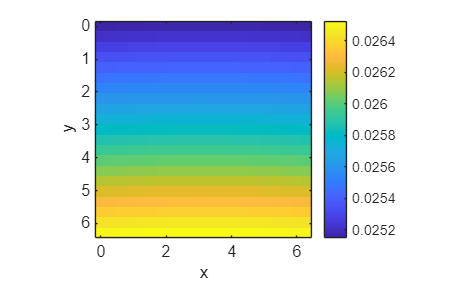


% Plot: absolute value
figure;
imagesc(x, y, abs(u_inc));
axis equal tight;
% title('Magnitude of Incident Field');
xlabel('x'), ylabel('y');
set(gca, 'YDir', 'reverse');
colorbar;

## Create a small gaussian like object for born approximation to work

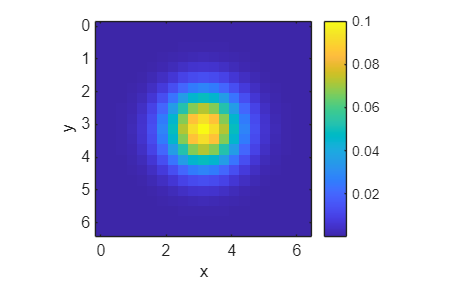

% Define a small Gaussian-like object (smooth and low contrast)
radius = 0.25 * lambda;                         % small radius
center = [0.5 * lambda, 0.5 * lambda];          % center of the object
sigma = radius / 2;                             % standard deviation for smooth edges
chi_max = 0.1;                                  % low contrast

% Calculate distance from center
dist2 = (X - center(1)).^2 + (Y - center(2)).^2;

% Smooth Gaussian contrast function
chi = chi_max * exp(-dist2 / (2 * sigma^2));

% Plot
figure;
imagesc(x, y, chi);
axis equal tight;
colorbar;
% title('Smooth Low-Contrast Object for Born Approximation');
set(gca, 'YDir', 'reverse');
xlabel('x'); ylabel('y');

Generate x vector

% Compute x by reshaping chi into a column vector of size N×1
x_chi = reshape(chi, [N, 1]);

Generate A matrix

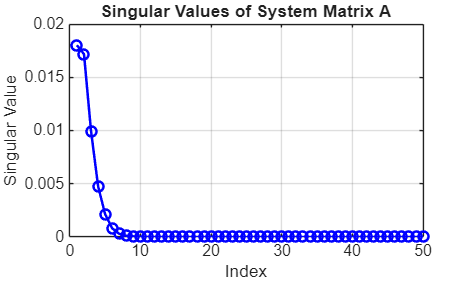

% Store receiver coordinates
rx = x_rec; 
ry = y_rec;

% Reshape the 2D grid points to a list of (x, y) pairs
x_grid = reshape(X, [N, 1]);
y_grid = reshape(Y, [N, 1]);

% Initialize system matrix A
A = zeros(M, N);

% Vectorized incident field in the object domain
u_inc_vec = reshape(u_inc, [N, 1]);

% Loop over receivers
for m = 1:M
    % Receiver location
    r_m = [rx(m), ry(m)];

    % Compute distances to all grid points
    dists = sqrt((x_grid - r_m(1)).^2 + (y_grid - r_m(2)).^2);  % Nx1

    % Green's function evaluations using Hankel function
    G = -1i/4 * besselh(0, 2, kb * dists);  % Nx1

    % Fill row m of A
    A(m, :) = (kb^2 * h^2) * G.' .* u_inc_vec.';
end

% Compute the singular values of A
s = svd(A);

% Plot singular values (linear scale)
figure;
plot(s, 'bo-', 'LineWidth', 1.5);
xlabel('Index');
ylabel('Singular Value');
title('Singular Values of System Matrix A');
grid on;

Q16

% Scattered field computation
u_sc = A * x_chi;   % u_sc is M×1

Q17 and Q18

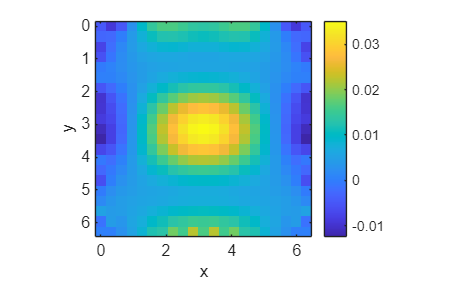

% Compute the pseudoinverse reconstruction of x
x_est = pinv(A) * u_sc;  % size N×1

% Reshape recovered x back to image grid (same as chi)
x_est_image = reshape(x_est, size(X));  % size n×n
figure;
imagesc(x, y, real(x_est_image));
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');
set(gca, 'YDir', 'reverse');

% title('Real Part of Reconstructed x');


Q20

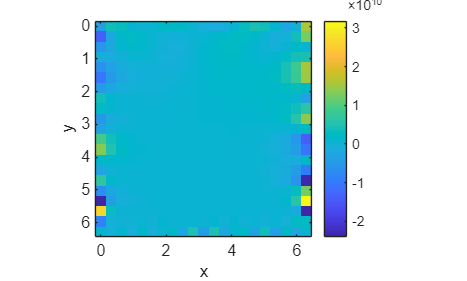

SNR_db = 20;
% Scattered field at the receiver with noise
u_sc = A * x_chi;   % u_sc is M×1
% Compute the energy of the signal
signal_energy = norm(u_sc)^2;  % Energy of the scattered field
% Compute the noise variance based on the desired SNR
noise_variance = signal_energy / (10^(SNR_db / 10));
% Sample complex gaussian noise
noise = sqrt(noise_variance / 2) * (randn(size(u_sc)) +  1i * randn(size(u_sc)));
% Add noise
u_sc_noisy = u_sc + noise;
% Compute the pseudoinverse reconstruction of x
x_est = pinv(A) * u_sc_noisy;  % size N×1

% Reshape recovered x back to image grid (same as chi)
x_est_image = reshape(x_est, size(X));  % size n×n
figure;
imagesc(x, y, real(x_est_image));
axis equal tight;
colorbar;
xlabel('x'); ylabel('y');
set(gca, 'YDir', 'reverse');

% title('Real Part of Reconstructed x');

Q15

% M_list = [20, 50, 100];
% 
% figure;
% hold on;
% for i = 1:length(M_list)
%     M = M_list(i);
% 
%     % Redefine receiver grid (assume x spans from -lambda to 2*lambda)
%     x_rec = linspace(-lambda, 2*lambda, M);
%     y_rec = -1.5 * lambda * ones(1, M);
% 
%     % Rebuild A (same loop as before)
%     A = zeros(M, N);
%     for m = 1:M
%         r_m = [x_rec(m), y_rec(m)];
%         dists = sqrt((x_grid - r_m(1)).^2 + (y_grid - r_m(2)).^2);
%         G = -1i/4 * besselh(0, 2, kb * dists);
%         u_inc_vec = reshape(u_inc, [N, 1]);
%         A(m, :) = (kb^2 * h^2) * G.' .* u_inc_vec.';
%     end
% 
%     % SVD and log plot
%     s = svd(A);
%     semilogy(s, 'LineWidth', 1.5, 'DisplayName', ['M = ' num2str(M)]);
% end
% 
% xlabel('Index');
% ylabel('Singular Value');
% % title('Singular Value Decay for Different Number of Receivers');
% legend show;
% grid on;